clc
close all force
clearvars

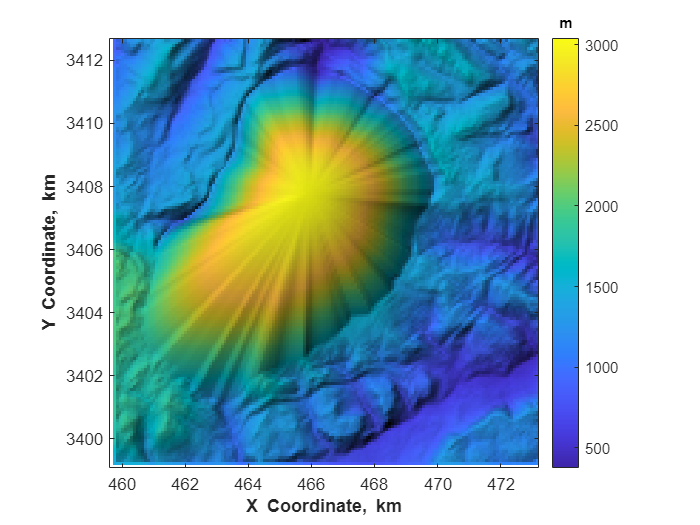

% input DEM data
DEM=GRIDobj('ttlem\DataForSimulate\WulongshanForTTLEM90.tif');
% input unreconstructed DEM data
DEM2 =GRIDobj('ttlem\DataForSimulate\Original.tif');

% read raster information
[~, R] = readgeoraster('ttlem\DataForSimulate\WulongshanForTTLEM90.tif');
% read raster information
[~, R2] = readgeoraster('ttlem\DataForSimulate\Original.tif');%读取栅格数据信息

% show DEM figure
imageschs(DEM,[],'ticksToKm',true,'colorBarLabel','\bfm');
xlabel('\bfX Coordinate, km');
ylabel('\bfY Coordinate, km')

% read different 
Boundaryt4 = shaperead('ttlem\DataForSimulate\plain.shp');

[row4, col4] = worldToIntrinsic(R,Boundaryt4.X(1:end-1),Boundaryt4.Y(1:end-1));
mask4 = poly2mask(row4,col4, DEM.size(1), DEM.size(2));

mydem=DEM;
[x,y]=getcoordinates(mydem);

[xgrid, ygrid] = meshgrid(x, y');

xgrid_vec=reshape(xgrid,1,numel(mydem.Z));
ygrid_vec=reshape(ygrid,1,numel(mydem.Z));

demgrid_vec=reshape(DEM.Z,1,numel(mydem.Z));
x_points=xgrid_vec(demgrid_vec>2100);
y_points=ygrid_vec(demgrid_vec>2100);
z_points=demgrid_vec(demgrid_vec>2100);
fitobject = fit([x_points',y_points'],z_points','poly33');

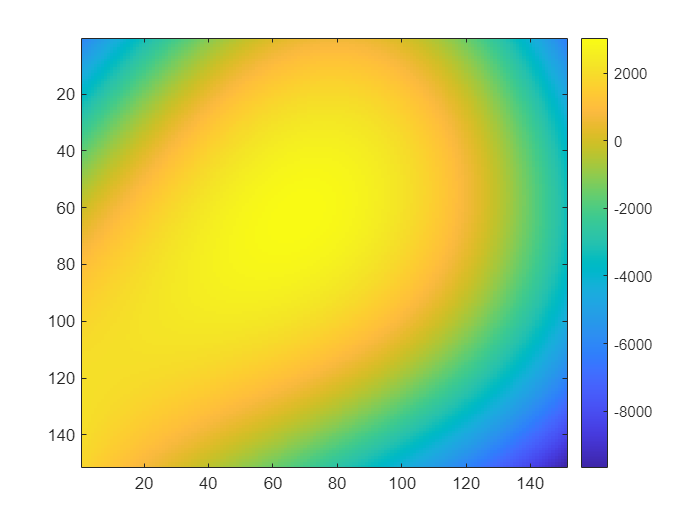

%plot(fitobject,[x_points',y_points'],z_points')
zhat=fitobject(xgrid,ygrid);

imagesc(zhat);
colorbar

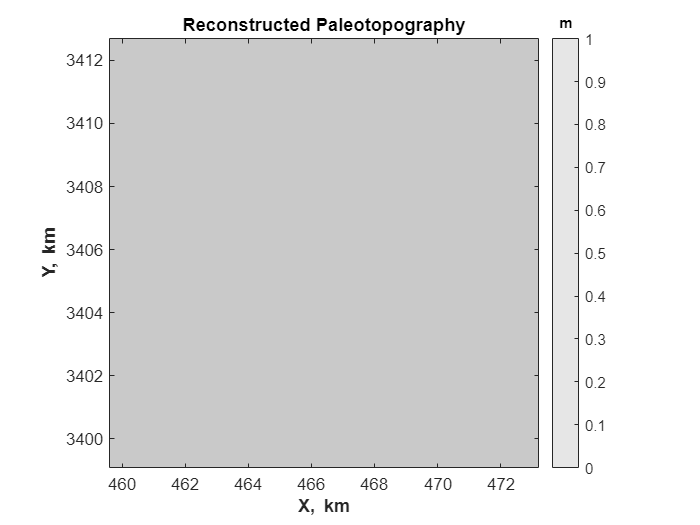


irregularArea = DEM;
ThreeDGEOL=DEM;
ThreeDGEOL=zhat;

% set initial condition
irregularArea.Z(:,:) =5000;

imageschs(irregularArea,[],'ticksToKm',true,'colorBarLabel','\bfm','colormap',[.9 .9 .9]);

xlabel('\bfX, km');
ylabel('\bfY, km');
title('Reconstructed Paleotopography')

% uplift rate
U = GRIDobj(DEM);

U.Z(1:end,1:end) =1e-5;

% Time Span
p.TimeSpan=15e6;
p.TimeStep=1e5;

% K_weight, now I try to set uniform situation all over the area, next I will set different situations.
K_weight = GRIDobj(DEM);
K_weight.Z(1:end,1:end)=1e-6;
p.K_weight = K_weight;

ttlem_out = struct with fields:
    H1: [1×1 GRIDobj]
     S: [1×1 STREAMobj]


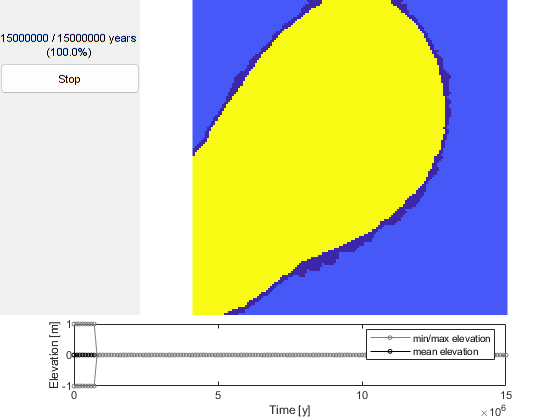

% hillslope processes
p.D=0.03;
p.diffScheme = 'imp_lin_Sc';
p.DiffTol = 1e-6;
p.Sc=1;
p.Sc_unit='tangent';

% boundary condition
p.BC_nbGhost=2;
p.BC_Type='Neumann';
p.BC_dir_value=100;
p.BC_dir_DistSites='t';
p.BC_dir_Dist_Value=0.5;


% River incision parameters
p.Kw = 1;
p.m  = 0.5;
p.n  = 1;
p.AreaThresh = 1e3;
p.DrainDir='variable';

% why set the m
%p.m_var=.3; 

p.riverInc = 'implicit_FDM';
p.cfls=0.95;

p.steadyState  = false;
p.SS_Value     = 1e-6*size(DEM.Z,1)*size(DEM.Z,2);
p.ploteach=1;
p.saveeach=1;
p.fileprefix='syntheticRun';
p = ttlemset(p);


% run the model
ttlem_out = ttlem_WD_Geology(irregularArea,U,p,ThreeDGEOL,mask4)


%imageschs(H1,[],'ticksToKm',true,'colorBarLabel','\bfm');

xlabel('\bfX Coordinate, km');
ylabel('\bfY Coordinate, km');

scrsz = get(0,'ScreenSize');
hFig  = figure('OuterPosition',[0.1*scrsz(4) 0.1*scrsz(4) .7*scrsz(4) .7*scrsz(4)])

hFig =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [116 116 740 717]
       Units: 'pixels'

  Show all properties


if strcmp(p.diffScheme,'imp_nonlin_sc')
    parameter=1e-10;
    inc=max(max(U.Z(:)),1e-3);
    dt_max=DEM.cellsize*DEM.cellsize/inc*max(p.Sc(:))*parameter/(p.D*p.Kw);
    dt_max=min(dt_max,5000);
    nbSteps=ceil(p.TimeSpan/dt_max);
    if (p.TimeSpan/nbSteps)<p.TimeStep
        p.TimeStep=p.TimeSpan/nbSteps;
        p.TimeStep       = p.TimeStep;
        disp(['Timestep is decreased to ' num2str(round(p.TimeStep))...
            ' yr in order to keep the non linear solution stable, see Perron 2011, JGR']);
    end
end

figure
files = dir([p.resultsdir p.fileprefix '*.mat']);
[~,ix] = sort([files.datenum]);
files = files(ix);

for r = 1:numel(files)
    t = p.TimeStep*r;
    
    load([p.resultsdir files(r).name],'H1');
    imageschs(H1,[],'tickstokm',true,'colorBarLabel','\bfm');
%     hold on
%     FD  = FLOWobj(H1,'preprocess','c');
%     S   = STREAMobj(FD,flowacc(FD)>(p.AreaThresh/FD.cellsize^2));
%     S.x = S.x*1e-3;
%     S.y = S.y*1e-3;
%     plot(S,'k','linewidth',1)
%     hold off
    xlabel('\bfX Coordinate, km')
    ylabel('\bfY Coordinate, km')
    title(['Standard Run ' num2str(round(t*1e-3)) 'k years']);

    
    drawnow
    
end

General Error occurred in WebControllerFactory::create()


Dot indexing is not supported for variables of this type.

Error in matlab.ui.internal.controller.SceneChannelController/updateSceneChannel (line 53)
                BinaryChannelID = 'hgBinary_'+ string(rootController.ProxyView.PeerNode.getId);

Error in 